## FORWARD PROBLEM SETUP

clear; clc; close all;
clearvars;

#### 1. Load Image

image_path = '296059.jpg';
img = imread(image_path);

% Convert to grayscale if RGB
if ndims(img) == 3
    img = mean(double(img), 3);
else
    img = double(img);
end

% Normalize to [0, 1]
x = img / max(img(:));

fprintf('Image shape: %d x %d\n', size(x, 1), size(x, 2));

Image shape: 321 x 481


#### 2. Gaussian Blur Kernel

kernel_size = 9;
sigma = 2.0;

half_size = floor(kernel_size / 2);
[xx, yy] = meshgrid(-half_size:half_size, -half_size:half_size);
kernel = exp(-(xx.^2 + yy.^2) / (2 * sigma^2));
kernel = kernel / sum(kernel(:));

#### 3. Forward Blur with Noise

noise_std = 0.01;
Ax = imfilter(x, kernel, 'symmetric', 'same');
eps = noise_std * randn(size(Ax));
y = Ax + eps;

#### 4. Visualization

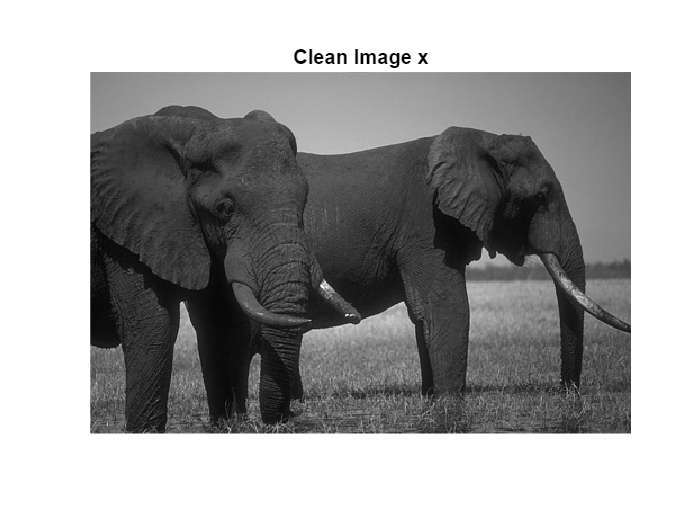

figure

% Clean image
imagesc(x);
colormap gray;
axis image off;
title('Clean Image x');

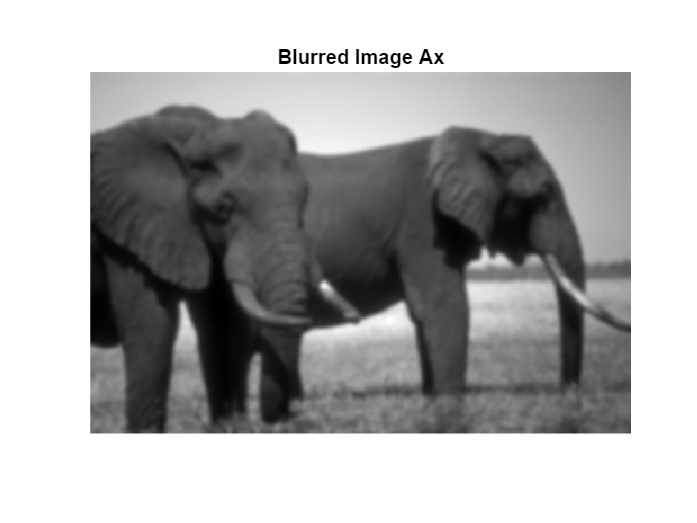


% Blurred image
imagesc(Ax);
colormap gray;
axis image off;
title('Blurred Image Ax');

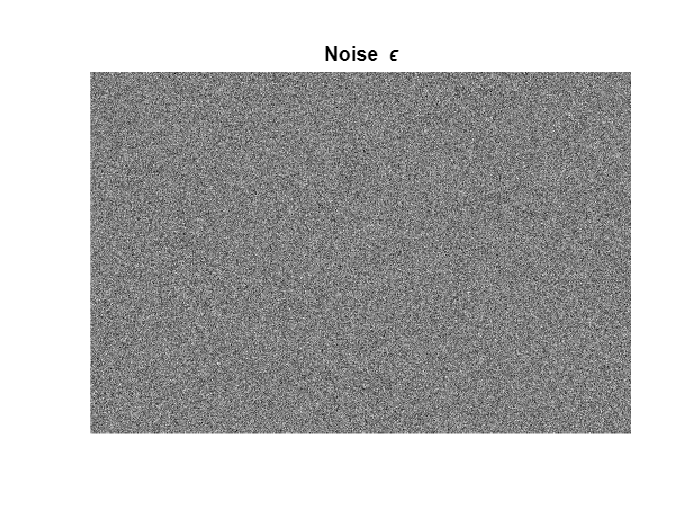


% Noise
imagesc(eps);
colormap gray;
axis image off;
title('Noise \epsilon');

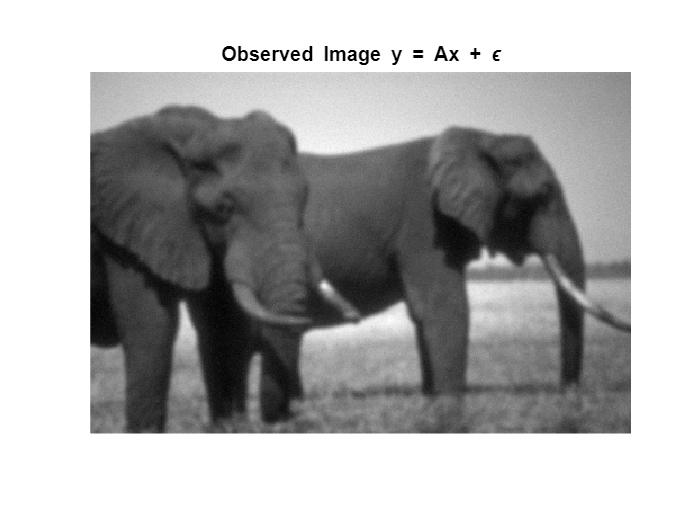


% Observed image
imagesc(y);
colormap gray;
axis image off;
title('Observed Image y = Ax + \epsilon');

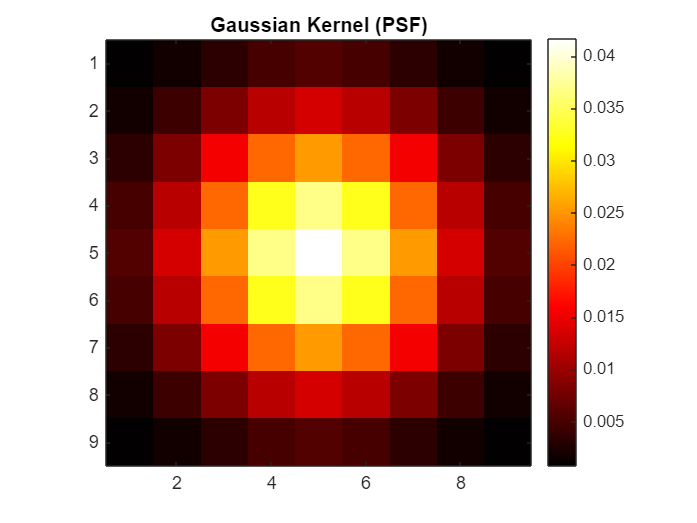


% Gaussian kernel (PSF)
imagesc(kernel);
colormap hot;
axis image;
colorbar;
title('Gaussian Kernel (PSF)');

#### 5. Quantitative Analysis

noise_norm = norm(eps(:));
signal_norm = norm(Ax(:));
relative_noise = noise_norm / signal_norm;

fprintf('Noise norm (||epsilon||): %.4f\n', noise_norm);

Noise norm (||epsilon||): 3.9260


fprintf('Signal norm (||Ax||): %.4f\n', signal_norm);

Signal norm (||Ax||): 163.7190


fprintf('Relative noise level (delta): %.4f\n', relative_noise);

Relative noise level (delta): 0.0240
